%H_Filter = tf([11.938e6 0 ],[1 11.938e6 7.896e12])
%bode(H_Filter)

H_Filter_fixed = tf([125.04e6 0 ],[1 125.04e6 7.896e13])


H_Filter_fixed =
 
          1.25e08 s
  --------------------------
  s^2 + 1.25e08 s + 7.896e13
 
Continuous-time transfer function.



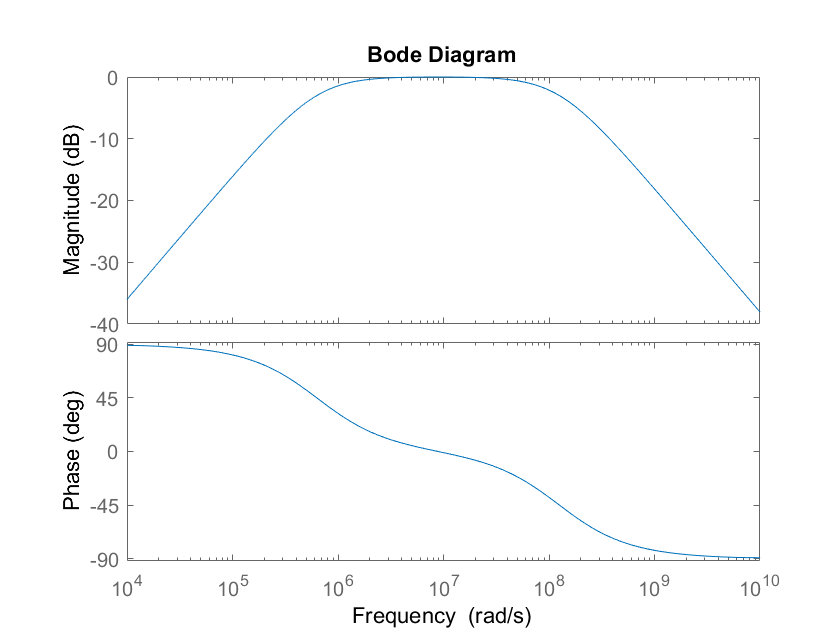

bode(H_Filter_fixed)


H_Sensor  = tf([187.77e6 0 ],[1 187.77e6 1.1838e14])


H_Sensor =
 
          1.878e08 s
  ---------------------------
  s^2 + 1.878e08 s + 1.184e14
 
Continuous-time transfer function.



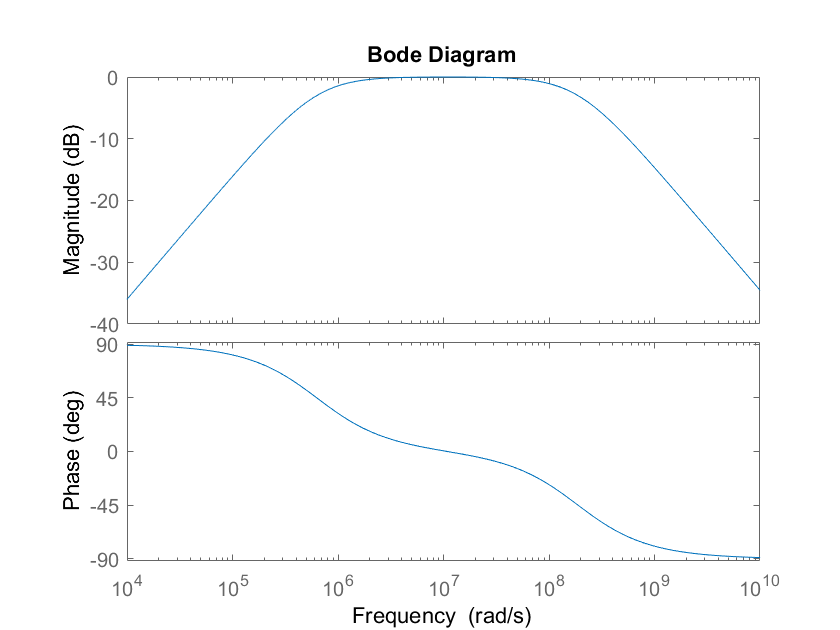

bode(H_Sensor)


%H_Amp  = tf([15],[1 2.283e6 ])
%bode(H_Amp)

H_Final=H_Sensor*H_Filter_fixed


H_Final =
 
                        2.348e16 s^2
  ---------------------------------------------------------
  s^4 + 3.128e08 s^3 + 2.368e16 s^2 + 2.963e22 s + 9.347e27
 
Continuous-time transfer function.



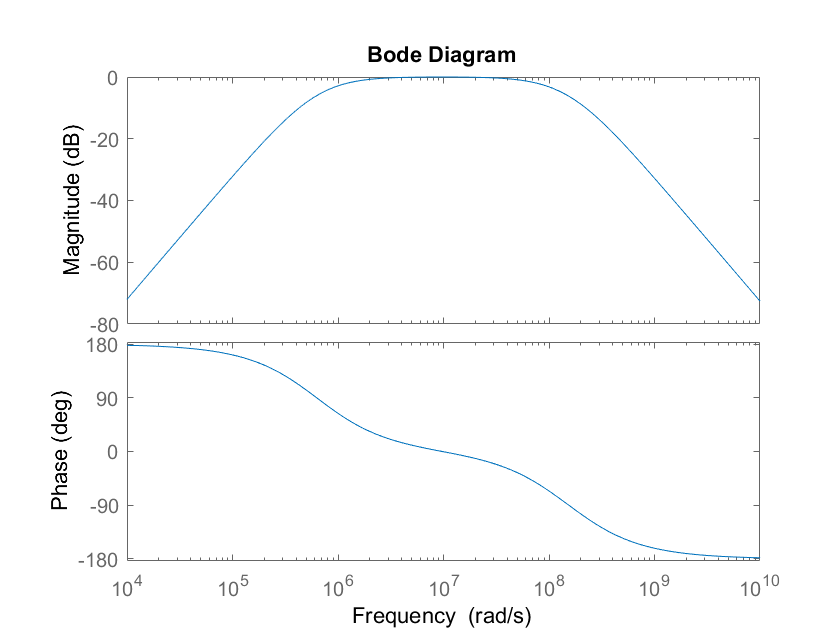

bode(H_Final)